# LECTURE WEEK II. - HANDS-ON

# SUPERPOSITION PRINCIPLE AND CONVOLUTION

## MATLAB HANDS-ON Assignment II.1: Determine unkown impulse response

**Completion requirements:**

- Explain your solution in one sentence.

- Show the plots of the six LTI filters.

You are given six LTI filters with an unkown input-output relation. Each of the "black-box" filters can be called through the following function:

where $xx$ is an input signal, $option$ is an integer between 1 and 6 that selects an LTI filter, and $yy$ is the resulting output signal. For each of the six LTI filters, determine and plot the impulse response.

***Answer:***

% Write your code here

## MATLAB HANDS-ON Assignment II.2: Improving quality of speech signal

**Completion requirements:**

- Explain (in one sentence per filter) how each of the five given FIR filters affect the speech quality

- Show the impulse response coefficients of your own FIR filter to the supervisors.

- Explain how your filter improves on the results of the other filters

You are given the speech signal '`data/code.wav`'. This speech signal is a degraded recording of a sentence. The objective is to improve the intelligibility of the speech, in particular to understand the numerical code expressed in the signal.

***(a)*** Read the speech signal into MATLAB and listen to the signal. What is the numerical code pronounced?

***Answer:***

% Write your code here

Code = 

We wish to improve the quality of the speech signal as so to better understand the numerical code. To that end, we consider various FIR filters. The first four filters (FIR1 to FIR4) are similar to the ones studied before during the class room lectures and in Session I and II of the hands-­on. The filter FIR5 has been specifically designed for this task of improving speech quality.

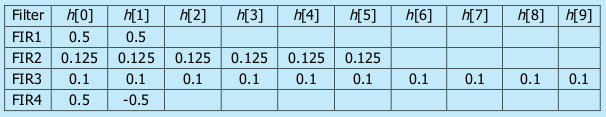

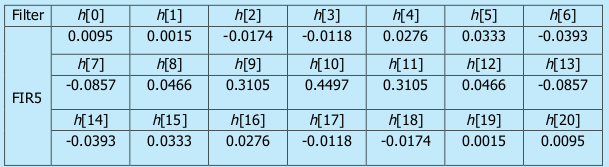

***(b)*** Filter the speech signal with each of these FIR filters using the convolution function `conv()`. Listen to the different output signals and determine which filter gives the best result. Which one gives the worst result? What is the numerical code?

***Answer:***

% Write your code here

Best = 

Worst = 

Code = 

How does each filter effect the signal:

***(c)*** Choose another FIR filter yourselves and try to improve the best result obtained in part ***(b)***. Write down the impulse response of the filter you selected.

***Answer:***

% Write your code here


$$h[n] = $$


How does your filter improve upon the others:

**Completion requirements:**

- Explain (in one sentence per filter) how each of the five given FIR filters affect the speech quality

- Show the impulse response coefficients of your own FIR filter to the supervisors.

- Explain how your filter improves on the results of the other filters

## MATLAB HANDS-ON Assignment II.3: Differential compression of audio

**Completion requirements:**

- Show the reproduced plot as required in assignment ***A***.

- Show the 2-D plot as required in assignment ***B***.

- Show and explain your MATLAB code leading to both plots

We continue the example given in class room lecture 1 of compressing an audio signal using a differential technique. The idea was that each audio sample can be predicted from previous samples. The simplest predication was to take a weighted version of the value of the previous sample (that is: $b_{1}x[n - 1]$) as an estimate for the current sample $x[n]$. If we denote the estimate/predication by $y[n]$, then the estimate is a simple first order FIR filter:


$$Estimate \Rightarrow y[n] = b_{1}x[n - 1]$$


and the remaining difference is:


$$\Delta x[n] = x[n] - y[n] = x[n] - b_{1} x[n - 1]$$


(Note that this is a second order FIR filter by itself).

The best value of $b_{1}$ minimizes the variance of the difference $\Delta x[n]$. In the lecture, a plot was shown that illustrates how this variance changes as we change $b_{1}$.

(a) Read the music file '`data/summervibe.wav`' into MATLAB. Reproduce the plot shown in the class room lecture to find the optimal value of $b_{1}$.

***Answer:***

% Write your code here

There is no reason to limit ourselves to using only the value $x[n - 1]$ immediatly preceding $x[n]$. We can also use the two preceding values, in which case the estimate is created by a second  order FIR filter:


$$Estimate \Rightarrow y[n] = b_{1}x[n - 1] + b_{2} x[n - 2]$$


The remaining difference now becomes:


$$\Delta x[n] = x[n] - y[n] = x[n] - b_{1} x[n - 1] - b_{2} x[n - 2]$$


(b) Write a MATLAB program to determine the optimal values for the pair ($b_{1}$, $b_{2}$) such that the variance of the difference is minimal. Illustrate the result by making a 2-D surface plot of the variance of the difference $\Delta x[n]$ as a function of the values ($b_{1}$, $b_{2}$). Use the MATLAB command `surf`.

***Answer:***

% Write your code here

**Completion requirements:**

- Show the reproduced plot as required in assignment ***A***.

- Show the 2-D plot as required in assignment ***B***.

- Show and explain your MATLAB code leading to both plots